# Teste do Pêndulo

22/04/2021  Arménio Correia   armenioc@isec.pt

Trabalho realizado por:(8/05/2021)

        Diogo Silva - 2020138438 - a2020138438@isec.pt

        Hugo Ferreira - 2020128305 - 2020128305@isec.pt

        Rúben Mendes  - 2020138473 - a2020138473@isec.pt

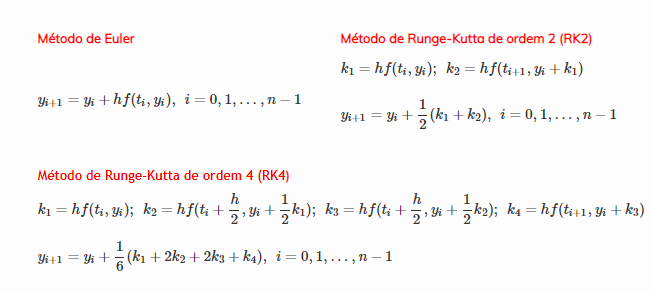

syms u(t) v(t)

f =@(t,u,v) v;
g =@(t,u,v) -16*u;
a = 0;
b = 15;
n = 100;
u0 = pi/2;
v0 = 0;


eqns = [diff(u,t)==v,diff(v,t)==-16*u];
ci = [u(0)==u0,v(0)==v0];
[sExataU,sExataV] = dsolve(eqns,ci);

h =@(t) eval(vectorize(char(sExataU)));


[t,uEuler,~] = NEulerSED(f,g,a,b,n,u0,v0);
[~,uRK2,~] = NRK2SED(f,g,a,b,n,u0,v0);

uExata = h(t);

erroEuler = abs(uExata-uEuler);
erroRK2 = abs(uExata-uRK2);


array2table([t.',uExata.', uEuler.',uRK2.',erroEuler.',erroRK2.'],...
            "VariableNames",{'t','Exata','Euler','RK2','erroEuler','erroRK2'})

plot(t,uExata,"-g+")
hold on
plot(t,uEuler,"-r*")
plot(t,uRK2,"-bo")
hold off
legend("Exata","Euler","RK2")